# Combustion Process from IVC to EVO

Polytropic compression and polytropic expansion processes are smoothly interpolated by the combustion rate function from Intake Valve Close (IVC) to Exhaust Valve Open (EVO).

## Inputs

p_ivc_kPa = 0.9*101.325;

T_ivc_K = 273.15 + 25;

% IVC: intake valve close
IVC_deg = 180+25;
IVC_rad = IVC_deg/180*pi;

% EVO: exhaust valve open
EVO_deg = 360+180-10;
EVO_rad = EVO_deg/180*pi;

% air/fuel ratio
afr = 14.7;

% SA: spark advance
SA_degBTDC = 50:-10:-50;
SA_rad = (360 - SA_degBTDC)./180*pi;

% crank angle range (X-axis)
ca_deg = transpose(linspace(IVC_deg, EVO_deg, 100));
ca_rad = ca_deg/180*pi;

## Combustion Parameters

% Wiebe function
comb_a = paramfcn_cylinder_gas_Wiebe_a();
comb_m = paramfcn_cylinder_gas_Wiebe_m();

% burn duration
BD_deg = paramfcn_cylinder_gas_Wiebe_burnDuration_deg()

BD_deg = 50

BD_rad = BD_deg/180*pi;

## Plot

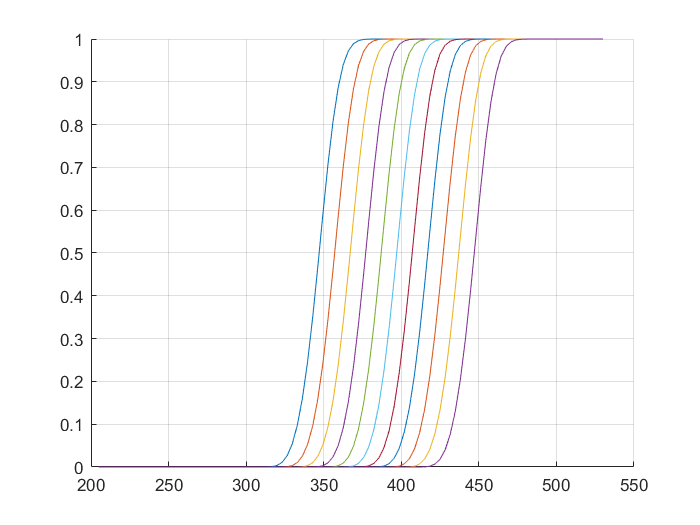

% Combustion weighting fuyction, PR.
PR = 1 - exp( -comb_a.*( (ca_rad - SA_rad)./BD_rad ).^(comb_m + 1) );
PR(ca_rad < SA_rad) = 0;
% BDC1=180deg, TDC1=360deg, BDC2=540deg, TDC0=TDC2=720deg
figure;  hold on;  grid on
plot(ca_deg, PR)

%lgd = legend(SA_degBTDC, 'Location','northwest');  % Legend is broken (bug)
%title(lgd, 'SA (degBTDC)')

## Cylinder Parameters

V_displ_mm3 = paramfcn_cylinder_V_displ_mm3()

V_displ_mm3 = 4.9956e+05

Bore_mm = paramfcn_cylinder_Bore_mm()

Bore_mm = 86

Stroke_mm = paramfcn_cylinder_Stroke_mm()

Stroke_mm = 86

l_conrod_mm = paramfcn_cylinder_Conrod_mm()

l_conrod_mm = 129.3000

R_crank_mm = Stroke_mm/2;  % Crank radius

k_c = paramfcn_cylinder_gas_Gamma_compression()

k_c = 1.2500

k_e = paramfcn_cylinder_gas_Gamma_expansion()

k_e = 1.3000

cv_J_perkg_perK = paramfcn_cylinder_gas_Cv_comp_J_perkg_perK()

cv_J_perkg_perK = 1.1528e+03

q_LHV_MJ_perkg = paramfcn_gasoline_LHV_MJ_perkg()

q_LHV_MJ_perkg = 44.3000

q_LHV_J_perkg = q_LHV_MJ_perkg*1e+6;
AFR_s = paramfcn_gasoline_AFR_stoich()

AFR_s = 14.7000

## Cylinder Equations

% Cylinder volume profile (Y-axis)
V_cyl_mm3 = cylinder_volume_mm3_matlab(ca_rad, V_displ_mm3, R_crank_mm, l_conrod_mm, Bore_mm);

% cylinder volume at IVC
V_ivc_mm3 = cylinder_volume_mm3_matlab(IVC_rad, V_displ_mm3, R_crank_mm, l_conrod_mm, Bore_mm)

V_ivc_mm3 = 9.8317e+05

% cylinder volume at spark (volume at Otto cycle's state 2-to-3 transition)
V_23_mm3 = cylinder_volume_mm3_matlab(SA_rad, V_displ_mm3, R_crank_mm, l_conrod_mm, Bore_mm)

V_23_mm3 = 	1.0e+05 *

    6.1356    5.7536    5.4348    5.1949    5.0461    4.9956    5.0461    5.1949    5.4348    5.7536    6.1356


% Otto cycle's operating point 2 (start of combustion), based on EN14-(7.40)
p_2_kPa = p_ivc_kPa.*( V_ivc_mm3 ./ V_23_mm3 ).^k_c

p_2_kPa =   164.4067  178.1653  191.3227  202.4262  209.9199  212.5748  209.9199  202.4262  191.3227  178.1653  164.4067


T_2_K   = T_ivc_K  .*( V_ivc_mm3 ./ V_23_mm3 ).^(k_c - 1)

T_2_K =   335.4493  340.8848  345.7772  349.7006  352.2522  353.1387  352.2522  349.7006  345.7772  340.8848  335.4493


% Temperature increase due to combustion
lambda = afr/AFR_s;  % afr is input
eta_comb = min(1, lambda);
dT_comb_K = q_LHV_J_perkg*eta_comb/((afr + 1)*cv_J_perkg_perK)

dT_comb_K = 2.4477e+03


% Heat generation due to combustion; Otto-cycle's state 2-to-3 transition
T_3_K = T_2_K + dT_comb_K;  % EN14-(7.45)
p_3_kPa = p_2_kPa.*T_3_K./T_2_K;  % EN14-(7.45)

% Compression process profile (Y-axis), EN14-(7.40)
p_compression_kPa = p_ivc_kPa.*( V_ivc_mm3 ./ V_cyl_mm3 ).^k_c;
T_compression_K   = T_ivc_K  .*( V_ivc_mm3 ./ V_cyl_mm3 ).^(k_c - 1);

% Expansion process profile (Y-axis), EN14-(7.43)
p_expansion_kPa = p_3_kPa.*( V_23_mm3 ./ V_cyl_mm3 ).^k_e      .*( 1 - (0.3/90).*SA_degBTDC );
  % Note that the right-most factor (1-__*SA) is not part of (7.43).
  % The original (7.43) is symmetric around TDC, but as Fiture 7.28 in EN14 shows,
  % the pressure profile is not symmetric around TDC.  This right-most factor is
  % to break the symmetry and make the pressure estimation more reasonable.
T_expansion_K = T_3_K  .*( V_23_mm3 ./ V_cyl_mm3 ).^(k_e - 1).*(0.5*(1+0.8)-(1-0.8)/100.*SA_degBTDC );
  % The same observation applies to the temperature profile.

% combined by the combustion weighting function
p_cyl = (1 - PR).*p_compression_kPa + PR.*p_expansion_kPa;
T_cyl = (1 - PR).*T_compression_K   + PR.*T_expansion_K;

## Plot

Cylinder Pressure Profile

Compare this plot with Figure 7.28 at p.188 in EN14.

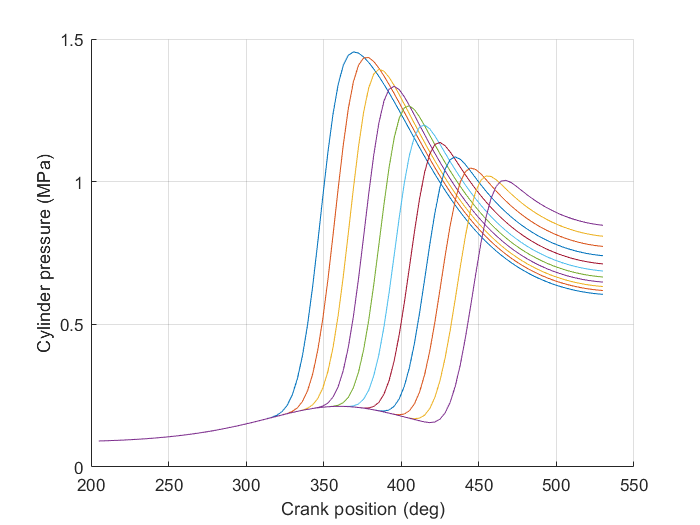

figure;  hold on;  grid on
%plot(ca_deg, p_compression_kPa/1e3)
%plot(ca_deg, p_expansion_kPa/1e3)
plot(ca_deg, p_cyl/1e3)
xlabel('Crank position (deg)')
ylabel('Cylinder pressure (MPa)')

Cylinder Temperature Profile

Compare this plot with Figure 7.35 at p.195 in EN14. While the current model uses rather simple formulation to estimate the gas temperature where the specific heat of the burned gas is assumed constant, the one used to produce Figure 7.35 is slightly more involved where the specific heat is modeled as a function of temperature, which is a more reasonable way to estimate the specific heat.

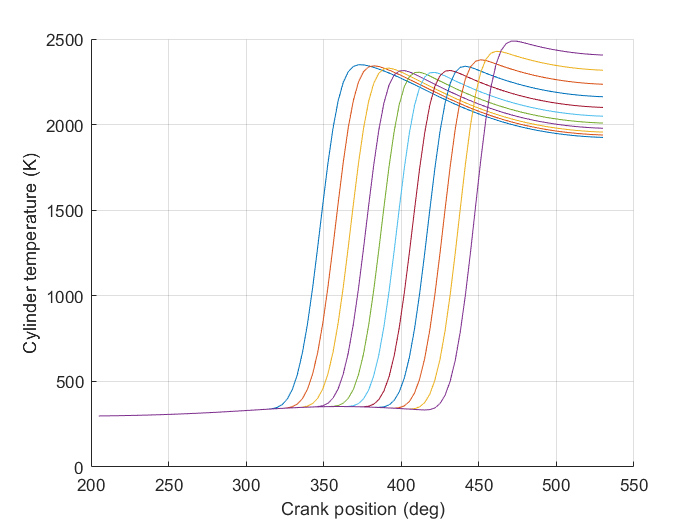

figure;  hold on;  grid on
%plot(ca_deg, T_compression_K)
%plot(ca_deg, T_expansion_K)
plot(ca_deg, T_cyl)
xlabel('Crank position (deg)')
ylabel('Cylinder temperature (K)')

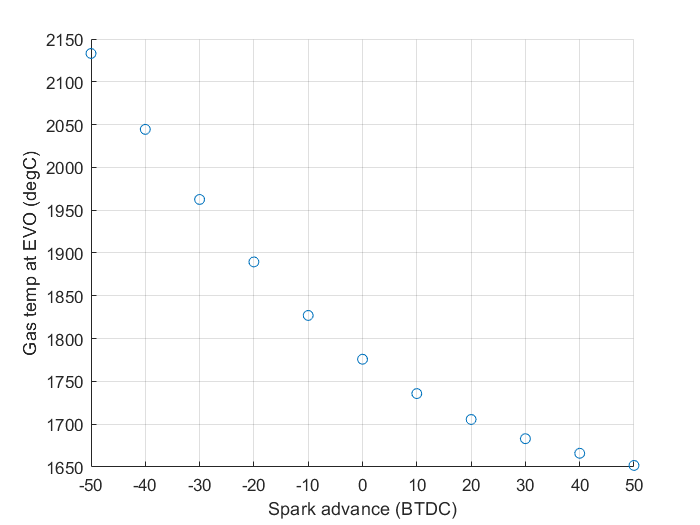

figure;  hold on;  grid on
scatter(SA_degBTDC, T_cyl(end,:)-273.15)
xlabel('Spark advance (BTDC)')
ylabel('Gas temp at EVO (degC)')